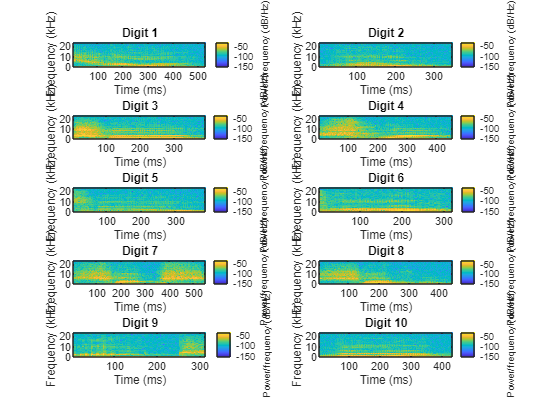

clear;
% %Exercício 9
Fs = 48000;
% %guardar dados 
energyThreshold = 0.003; % Definição do valor de energia mínimo considerada como silencio
windowSize = round(0.0064 * Fs); % Window size of 0.0032s
noverlap = round(0.0032 * Fs); % Overlap should be half the window size
nfft = 2^nextpow2(windowSize); % Number of points for the FFT

%PLOT
figure;

for i = 1:10
% Lê o primeiro audio de cada digito
    [audioData, samplingRate] = audioread(sprintf("Audios/%d_40_%d.wav", i-1, 0));

    % Pre-processamento
    audioData = removeSilence(audioData,energyThreshold);
    audioData = normalizeSignal(audioData);
    %audioData = fillSilence(audioData, 0.6, samplingRate);  %explicar pq é
    %nao usamos 

    % Cria o vetor de tempo
    time = (0:length(audioData)-1) / samplingRate;

    % Display the spectrogram
    subplot(5,2,i);
    spectrogram(audioData,hamming(windowSize),noverlap,nfft,samplingRate,'yaxis')
    title(sprintf('Digit %d',i))
end

ans = logical
   0


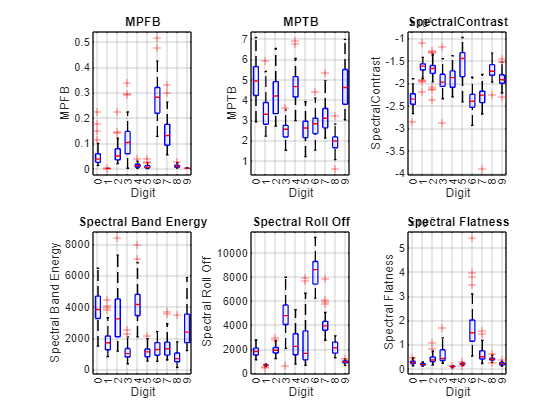




%exercicio 10
maxFrequencyBands = nfft /2 +1;
maxTimeWindows = 200;
audioSignals = cell(50, 1);  

meanPowerPerFrequencyBandPerDigit = cell(10, 1);
meanPowerPerTimeBandPerDigit = cell(10, 1);
meanspectralContrastPerTimeBandPerDigit = cell(10, 1);
meanspectralBandEnergyPerTimeBandPerDigit = cell(10, 1);
meanspectralRollOffPerTimeBandPerDigit = cell(10, 1);
meanspectralFlatnessPerTimeBandPerDigit = cell(10, 1);
meanpeakPowerPerTimeBandPerDigit = cell(10, 1);
meanpowerPerTimeWindowPerDigit = cell(10, 1);
meanspectralFluxPerTimeBandPerDigit = cell(10, 1);
meanpowerStdDevPerTimeBandPerDigit = cell(10, 1);
meanfrequencyStdDevPerTimeBandPerDigit = cell(10, 1);


totalMPFB = [];
totalMPTB = [];
totalspectralContrastPerTimeBand = [];
totalspectralBandEnergyPerTimeBand = [];
totalspectralRollOffPerTimeBand = [];
totalspectralFlatnessPerTimeBand = [];
totalpeakPowerPerTimeBand = [];
totalpowerPerTimeWindow = [];
totalspectralFluxPerTimeBand = [];
totalpowerStdDevPerTimeBand = [];
totalfrequencyStdDevPerTimeBand = [];


MPFBperdigit = [];
MPTBperdigit = [];
SCPTBperdigit = [];
SBEPTperdigit = [];
SROPTBperdigit = [];
PPPTBperdigit = [];
PPTWperdigit = [];
SFPTBperdigit = [];
SFluxPTBperdigit = [];
PSDPTBperdigit = [];
FSPTBperdigit = [];



% These matrices will have 50 rows, one for each sample, and f or t columns, one for each frequency band or time window
% We will then calculate the mean of each column to get the mean of each frequency band or time window over the 50 samples

for i = 1:10

 
    MPFBperdigit = [];
    MPTBperdigit = [];
    SCPTBperdigit = [];
    SBEPTperdigit = [];
    SROPTBperdigit = [];
    PPPTBperdigit = [];
    PPTWperdigit = [];
    SFPTBperdigit = [];
    SFluxPTBperdigit = [];
    PSDPTBperdigit = [];
    FSPTBperdigit = [];
    
    for s = 1:50
        [audioData, samplingRate] = audioread(sprintf("Audios/%d_40_%d.wav", i-1, s-1));
        audioData = removeSilence(audioData,energyThreshold);
        audioData = normalizeSignal(audioData);
        audioData = fillSilence(audioData, 0.6, samplingRate);

        [s, f, t] = spectrogram(audioData, hamming(windowSize), noverlap, nfft, Fs, 'yaxis');

        powerSpectrum = abs(s) .^ 2;
        frequencySpectrum = abs(fft(audioData));

        

        curSpectralContrastPerTimeBand = spectral_contrast(powerSpectrum, samplingRate); 
        curSpectralBandEnergyPerTimeBand = bandpower(powerSpectrum);
        curSpectralRollOffPerTimeBand = arrayfun(@(i) spectral_rolloff(powerSpectrum(:,i), samplingRate, 0.85), 1:size(powerSpectrum, 2));
        curSpectralFlatnessPerTimeBand = spectral_flatness(powerSpectrum);
        curPeakPowerPerTimeBand = max(powerSpectrum, [], 1);
        curPowerPerTimeWindow = sum(powerSpectrum, 1);
        curSpectralFluxPerTimeBand = spectral_flux(powerSpectrum);%Criar função
        curPowerStdDevPerTimeBand = std(powerSpectrum, 0, 1);

        % Calculate the weighted mean frequency for each time window
        meanFrequencyPerTimeWindow = sum(bsxfun(@times, f, powerSpectrum), 1) ./ sum(powerSpectrum, 1);

        % Subtract the mean frequency from each frequency
        frequencyDeviation = bsxfun(@minus, f, meanFrequencyPerTimeWindow);

        % Calculate the weighted standard deviation for each time window
        curFrequencyStdDevPerTimeBand = sqrt(sum(bsxfun(@times, powerSpectrum, frequencyDeviation .^ 2), 1) ./ sum(powerSpectrum, 1));

         % Calculate the mean power per frequency band
        curMPFB = mean(powerSpectrum, 2)'; % Column Matrix, transposed to be a row matrix
        curMPTB = mean(powerSpectrum, 1); % Row Matrix
       

        MPTB = padWithZeros(curMPTB, maxFrequencyBands);
        MPFB = padWithZeros(curMPFB, maxFrequencyBands);
        spectralContrastPerTimeBand= padWithZeros(curSpectralContrastPerTimeBand, maxFrequencyBands);
        spectralBandEnergyPerTimeBand = padWithZeros(curSpectralBandEnergyPerTimeBand, maxFrequencyBands);
        spectralRollOffPerTimeBand = padWithZeros(curSpectralRollOffPerTimeBand, maxFrequencyBands);
        spectralFlatnessPerTimeBand = padWithZeros(curSpectralFlatnessPerTimeBand, maxFrequencyBands);
        peakPowerPerTimeBand = padWithZeros(curPeakPowerPerTimeBand, maxFrequencyBands);
        powerPerTimeWindow = padWithZeros(curPowerPerTimeWindow, maxFrequencyBands);
        spectralFluxPerTimeBand = padWithZeros(curSpectralFluxPerTimeBand, maxFrequencyBands);
    	powerStdDevPerTimeBand = padWithZeros(curPowerStdDevPerTimeBand, maxFrequencyBands);
        frequencyStdDevPerTimeBand = padWithZeros(curFrequencyStdDevPerTimeBand, maxFrequencyBands);


        MPFBperdigit = [MPFBperdigit; MPFB];
        MPTBperdigit = [MPTBperdigit; MPTB];
        SCPTBperdigit = [SCPTBperdigit; spectralContrastPerTimeBand];
        SBEPTperdigit = [SBEPTperdigit; spectralBandEnergyPerTimeBand];
        SROPTBperdigit = [SROPTBperdigit; spectralRollOffPerTimeBand];
        SFPTBperdigit = [SFPTBperdigit; spectralFlatnessPerTimeBand];
        PPPTBperdigit = [PPPTBperdigit; peakPowerPerTimeBand];
        PPTWperdigit = [PPTWperdigit; powerPerTimeWindow];
        SFluxPTBperdigit = [SFluxPTBperdigit; spectralFluxPerTimeBand];
        PSDPTBperdigit = [PSDPTBperdigit; powerStdDevPerTimeBand];
        FSPTBperdigit = [FSPTBperdigit; frequencyStdDevPerTimeBand];

        totalMPFB = [totalMPFB; MPFB];
        totalMPTB = [totalMPTB; MPTB];
        totalspectralContrastPerTimeBand = [totalspectralContrastPerTimeBand; spectralContrastPerTimeBand];
        totalspectralBandEnergyPerTimeBand = [totalspectralBandEnergyPerTimeBand; spectralBandEnergyPerTimeBand];
        totalspectralRollOffPerTimeBand = [totalspectralRollOffPerTimeBand; spectralRollOffPerTimeBand];
        totalspectralFlatnessPerTimeBand = [totalspectralFlatnessPerTimeBand; spectralFlatnessPerTimeBand];
        totalpeakPowerPerTimeBand = [totalpeakPowerPerTimeBand; peakPowerPerTimeBand];
        totalpowerPerTimeWindow = [totalpowerPerTimeWindow; powerPerTimeWindow];
        totalspectralFluxPerTimeBand = [totalspectralFluxPerTimeBand; spectralFluxPerTimeBand];
        totalpowerStdDevPerTimeBand = [totalpowerStdDevPerTimeBand; powerStdDevPerTimeBand];
        totalfrequencyStdDevPerTimeBand = [totalfrequencyStdDevPerTimeBand; frequencyStdDevPerTimeBand];

    end

      digitopara2dlMPFB{i} = MPFBperdigit;
      digitopara2dlMPTB{i} = MPTBperdigit;
      digitopara2dtotalspectralContrastPerTimeBand{i} = SCPTBperdigit;
      digitopara2dtotalspectralBandEnergyPerTimeBand{i} = SBEPTperdigit;
      digitopara2dtotalspectralRollOffPerTimeBand{i} = SROPTBperdigit;
      digitopara2dtotalspectralFlatnessPerTimeBand{i} = SFPTBperdigit;
      digitopara2dtotalpeakPowerPerTimeBand{i} = PPPTBperdigit;
      digitopara2dtotalpowerPerTimeWindow{i} = PPTWperdigit;
      digitopara2dtotalspectralFluxPerTimeBand{i} = SFPTBperdigit;
      digitopara2dtotalpowerStdDevPerTimeBand{i} = PSDPTBperdigit;
      digitopara2dtotalfrequencyStdDevPerTimeBand{i} = FSPTBperdigit;


     %Turn the matrix into a vector by getting the mean of each column
     meanPowerPerFrequencyBandPerDigit{i} = mean(MPFBperdigit, 1);
     meanPowerPerTimeBandPerDigit{i} = mean(MPTBperdigit, 1);
     meanspectralContrastPerTimeBandPerDigit{i} = mean(SCPTBperdigit,1);
     meanspectralBandEnergyPerTimeBandPerDigit{i} = mean(SBEPTperdigit, 1);
     meanspectralRollOffPerTimeBandPerDigit{i} = mean(SROPTBperdigit, 1);
     meanspectralFlatnessPerTimeBandPerDigit{i} = mean(SFPTBperdigit, 1);
     meanpeakPowerPerTimeBandPerDigit{i} = mean(PPPTBperdigit, 1);
     meanpowerPerTimeWindowPerDigit{i} = mean(PPTWperdigit, 1);
     meanspectralFluxPerTimeBandPerDigit{i} = mean(SFluxPTBperdigit, 1);
     meanpowerStdDevPerTimeBandPerDigit{i} = mean(PSDPTBperdigit, 1);
     meanfrequencyStdDevPerTimeBandPerDigit{i} = mean(FSPTBperdigit,1);
    
end


% matrizpara2d = {meanPowerPerFrequencyBandPerDigit,meanPowerPerTimeBandPerDigit,meanspectralContrastPerTimeBandPerDigit,meanspectralBandEnergyPerTimeBandPerDigit,meanspectralRollOffPerTimeBandPerDigit,meanspectralFlatnessPerTimeBandPerDigit,meanpeakPowerPerTimeBandPerDigit,meanpowerPerTimeWindowPerDigit,meanspectralFluxPerTimeBandPerDigit, meanpowerStdDevPerTimeBandPerDigit,meanfrequencyStdDevPerTimeBandPerDigit};
% matrizpara3d = {totalMPFB, totalMPTB, totalspectralContrastPerTimeBand, totalspectralBandEnergyPerTimeBand, totalspectralRollOffPerTimeBand , totalspectralFlatnessPerTimeBand, totalpeakPowerPerTimeBand, totalpowerPerTimeWindow, totalspectralFluxPerTimeBand, totalpowerStdDevPerTimeBand,totalfrequencyStdDevPerTimeBand};
% labelsgraficos = {'Mean Power per Frequency Band for Each Digit', 'Mean Power per Frequency Band for Each Digit','spectralContrastPerTimeBandPerDigit','spectralBandEnergyPerTimeBandPerDigit','spectralRollOffPerTimeBandPerDigit','spectralFlatnessPerTimeBandPerDigit','peakPowerPerTimeBandPerDigit','powerPerTimeWindowPerDigit','spectralFluxPerTimeBandPerDigit','powerStdDevPerTimeBandPerDigit','frequencyStdDevPerTimeBandPerDigit'};
% 
% meta3plot(matrizpara2d,labelsgraficos)
% 
% figure;
% plot3DScatterPlot(totalMPTB, 'mean power per time band 3D', 'Time Band', 'Sample/(Digit+1)', 'Power(dB)');
% 
% 
% 
% figure;
% plot3DScatterPlot(totalMPFB, 'Mean Power per Frequency Band 3D', 'Time Band', 'Sample/(Digit+1)', 'Power(dB)'); 
% for i = 1:size(matrizpara3d,2)
%     figure;
%     plot3DScatterPlot(matrizpara3d{i}, labelsgraficos{i}, 'Frequency Band', 'Sample/(Digit+1)', 'Power(dB)'); 
% end
m1 = cell(10,50);
m2 = cell(10,50);
m3 = cell(10,50);
m4 = cell(10,50);
m5 = cell(10,50);
m6 = cell(10,50);
m7 = cell(10,50);
m8 =cell(10,50);
m9 = cell(10,50);
m10 = cell(10,50);
m11 =cell(10,50);
for i = 1:10
    for j = 1:50
        m1{i, j} =  median(digitopara2dlMPFB{i}(j, :));
        m2{i, j} = mean(digitopara2dlMPTB{i}(j, :));
        m3{i,j} = mean(digitopara2dtotalspectralContrastPerTimeBand{i}(j, :));
        m4{i,j} = mean(digitopara2dtotalspectralBandEnergyPerTimeBand{i}(j, :));
        m5{i,j} = mean(digitopara2dtotalspectralRollOffPerTimeBand{i}(j, :));
        m6{i,j} = mean(digitopara2dtotalspectralFlatnessPerTimeBand{i}(j, :));
        m7{i,j} = mean(digitopara2dtotalpeakPowerPerTimeBand{i}(j, :));
        m8{i,j} = mean(digitopara2dtotalpowerPerTimeWindow{i}(j, :));
        m9{i,j} = mean(digitopara2dtotalspectralFluxPerTimeBand{i}(j, :));
        m10{i,j} = mean(digitopara2dtotalpowerStdDevPerTimeBand{i}(j, :));
        m11{i,j} = mean(digitopara2dtotalfrequencyStdDevPerTimeBand{i}(j, :));
    end
end

matrices1 = {cell2mat(m1)',cell2mat(m2)',cell2mat(m3)',cell2mat(m4)',cell2mat(m5)',cell2mat(m6)'};
matrices2 = {cell2mat(m7)',cell2mat(m8)',cell2mat(m9)',cell2mat(m10)'};

labels1 = {'MPFB', 'MPTB','SpectralContrast','Spectral Band Energy', 'Spectral Roll Off', 'Spectral Flatness'};
labels2 = {'Peak Power','Power per Time Window', 'Spectral Flux', 'powerStd', };
plotBoxplots(matrices1, labels1);

ans = logical
   0


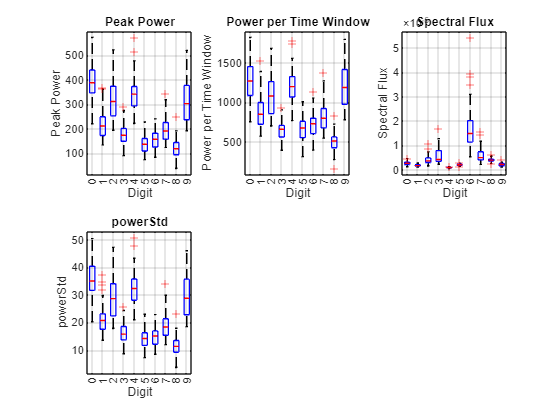

plotBoxplots(matrices2,labels2);

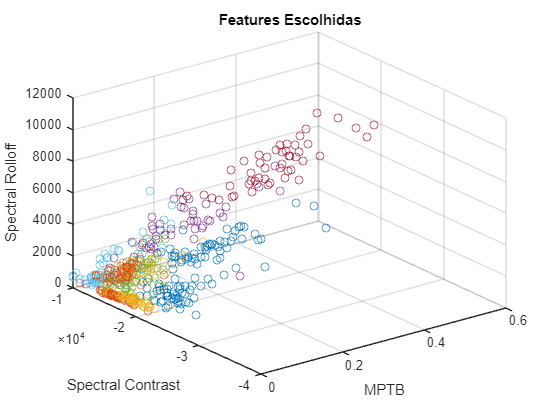


figure;
scatter3(cell2mat(m1)', cell2mat(m3)', cell2mat(m5)')
xlabel('MPTB');
ylabel('Spectral Contrast');
zlabel('Spectral Rolloff');
title('Features Escolhidas');